%Punkty pracy

clear all;
% hpp  = [27.2 45.6 64 82.4 100.8];
hpp  = [36 54 72 90 108];
Fpp = zeros(length(hpp), 1);

t_span = 1:2000; Ts = 10; 
alfa1 = 13; alfa2 = 12;
z_signal = ones(floor(length(t_span)/Ts), 1) * 15;

figure;
for i = 1:length(hpp)

    Fpp(i)  = calculate_Upp(hpp(i),15);
    
    % subplot(3,2,i)
    % h2_0_lin = hpp(i);
    % h1_0_lin = h2_0_lin * (alfa2 / alfa1)^2;
    % u_signal = ones(floor(length(t_span)/Ts), 1) * Fpp(i);
    % [~, h] = linear_tank_model(t_span, h1_0_lin, h2_0_lin, h2_0_lin, Ts, u_signal, z_signal);
    % stairs(h);
end






% s

S = [];
% figure;
for i = 1:length(hpp)
    s = get_s_lin(2000, Ts, hpp(i), Fpp(i));
    S = [S s];
    % stairs(1:length(s), s);
    % hold on
end
% legend('hpp=36', 'hpp=54', 'hpp=72', 'hpp=90', 'hpp=108')
% hold off

%function
% [mf_h1, mf_h2] = generate_gaussian_mf_functions(5);
% [mf_h1, mf_h2] = generate_trapezoidal_mf_functions(5);
[mf_h1, mf_h2] = generate_sigmoid_mf_functions(5);

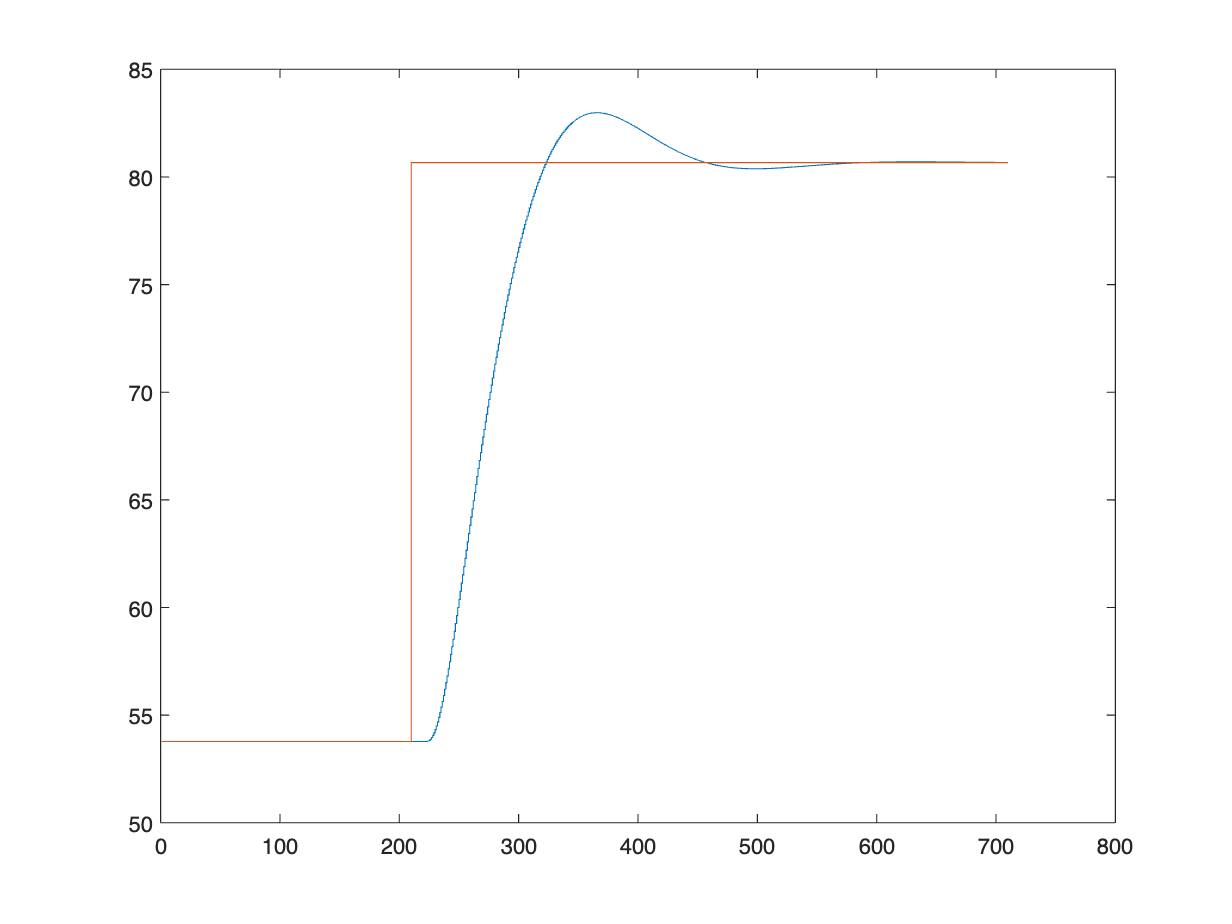

%fuzzy DMC 
model_count = 5; 
D = 200; N = 10; Nu = 2; lambda = [200 110 100 90 90];

ks = D+10; kk = ks+500; 
Upp = 73;
h1_0 = 45.8225;            
h2_0 = 53.7778;

z = 15;
z_signal = ones(floor(length(t_span)/Ts)*(kk+ks), 1) * z;
ke = [];
Ku = [];


for i = 1:model_count
    [~, ~, ~, ke_new, Ku_new] = offline_DMC(S(:,i), D, N, Nu, lambda(i));
    ke(end+1) = ke_new;
    Ku(:,end+1) = Ku_new;
end

h_zad(1:ks-1) = h2_0; h_zad(ks:kk) = 1.5*h2_0; 
h1(1:ks-1) = h1_0;
h1(ks:kk) = 0;
h2(1:ks-1) = h2_0;
h2(ks:kk) = 0;
u(1:ks-1) = Upp;
u(ks:kk) = 0;
e(1:kk) = 0;
delta_u(1:kk) = 0;


for k = ks:kk

    t_span_dmc = ((k-1)*Ts):(k*Ts);
    [~, h] = nonlinear_tank_model(t_span_dmc, h1_0, h2_0, Ts, u, z_signal);

    h1(k) = h(end,1); 
    h2(k) = h(end,2);
    h1_0 = h1(k);
    h2_0 = h2(k);

    e(k) = h_zad(k) - h2(k);

    delta_u_temp(1:model_count) = 0;
   
    for i = 1:model_count

        delta_sum = 0;
        for j = 1:D-1
            delta_sum = delta_sum + Ku(j,i)*delta_u(k-j);
        end
        delta_u_temp(i) = ke(i)*e(k) - delta_sum;
    end

    w = calculateFuzzyWeights(h1_0, h2_0, mf_h1, mf_h2);
    delta_u(k) = delta_u_temp * w;

    % delta_u(k) = min(max(delta_u(k), min_delta_u), max_delta_u);

    u(k) = delta_u(k) + u(k-1);
    u(k) = max(u(k), 0);
end

figure;
stairs(h2);
hold on
% stairs(h1);
stairs(h_zad);
% legend('h2', 'h1','h_zad')
hold off

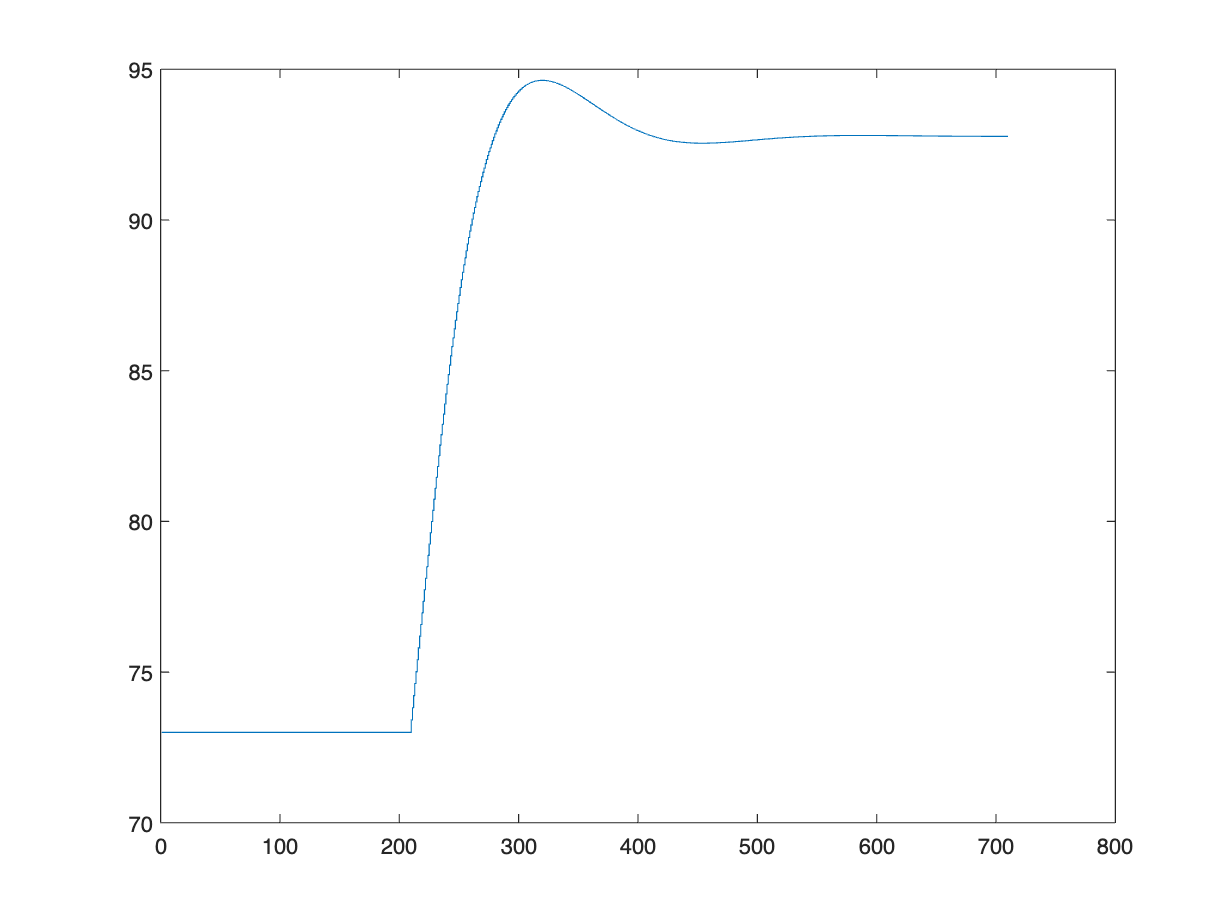


stairs(u);


E = sum((h_zad - h2).^2)

E = 3.4092e+04

% E = 36667.6149385054 trapez 1.5*hpp
% E = 3.6147e+04 gaus 1.5*hpp
% E = 3.4092e+04 sigmoidalna 1.5*hpp

